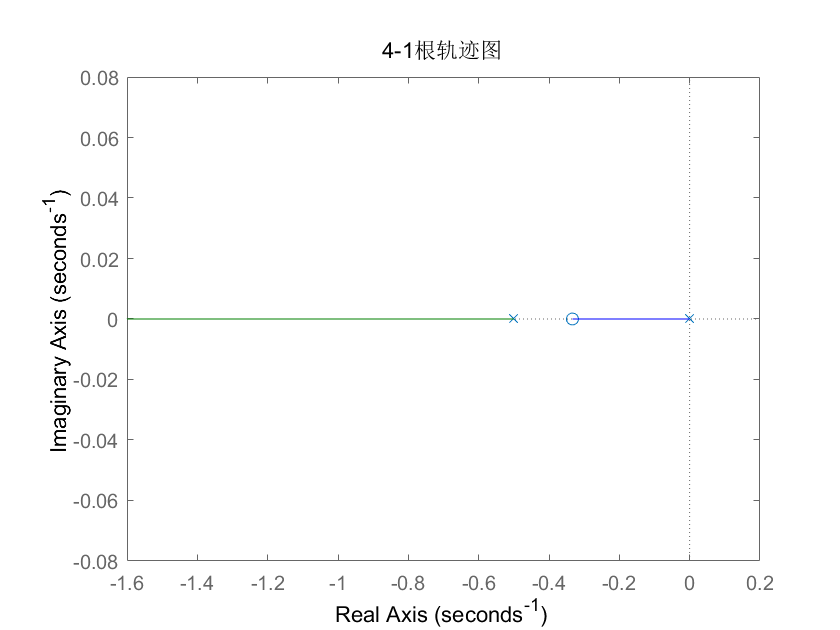

sys =
 
     100 (s+1)
  ----------------
  s (s-10) (s+0.1)
 
Continuous-time zero/pole/gain model.



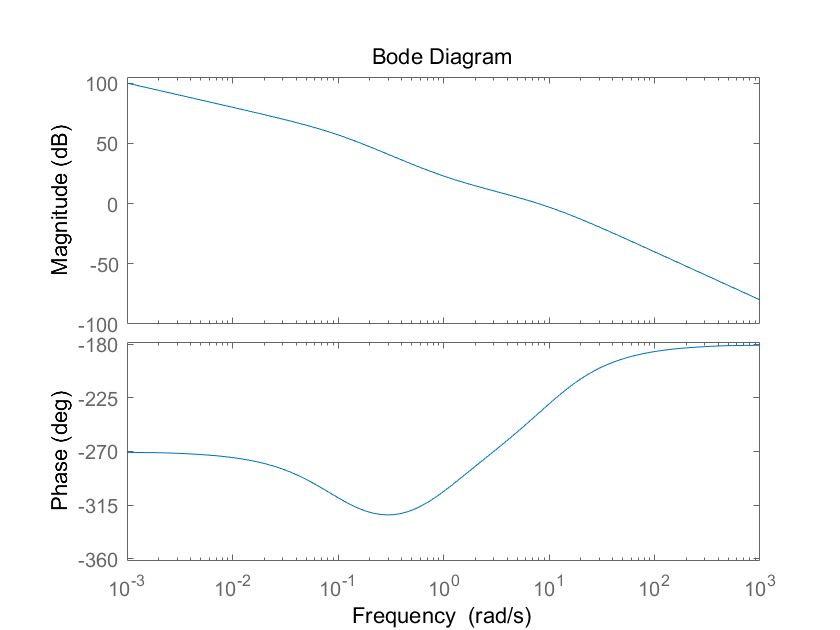

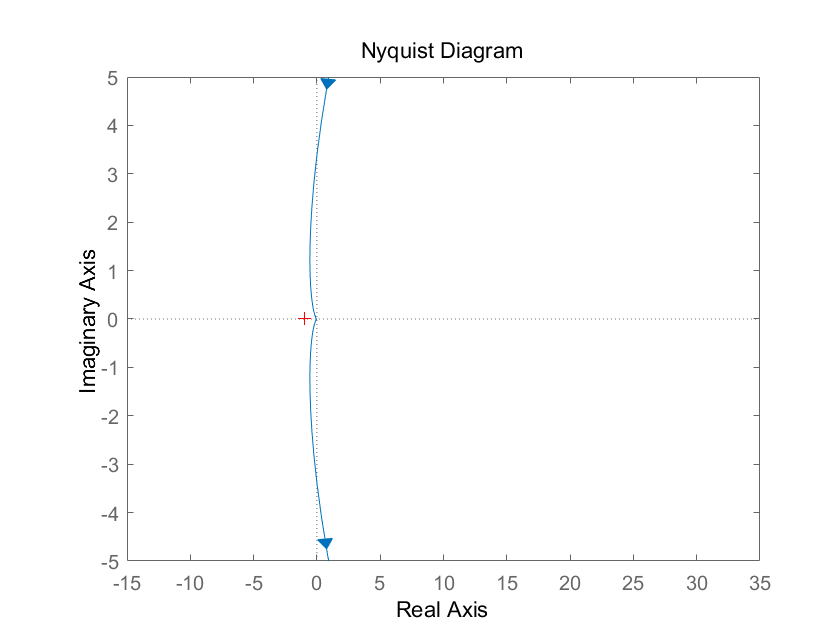

% 4-1
clear
G = tf([3 1],[2 1 0]);
rlocus(G);
title('4-1根轨迹图');

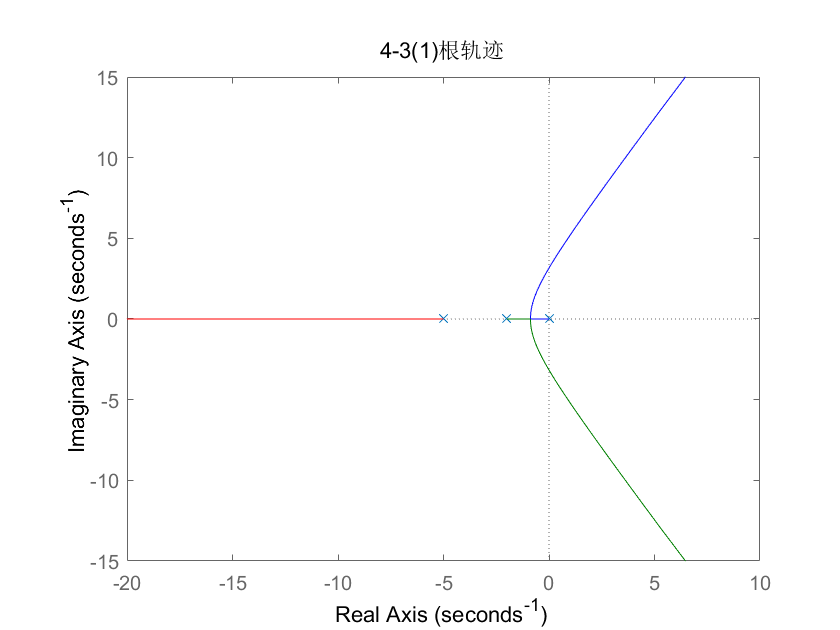

% 4-3
clear
G1 = zpk([],[0 -5 -2],1);
G2 = zpk([-1],[0 -0.5],1);
G3 = zpk([-5],[0,-2,-3],1);
rlocus(G1);
title('4-3(1)根轨迹');

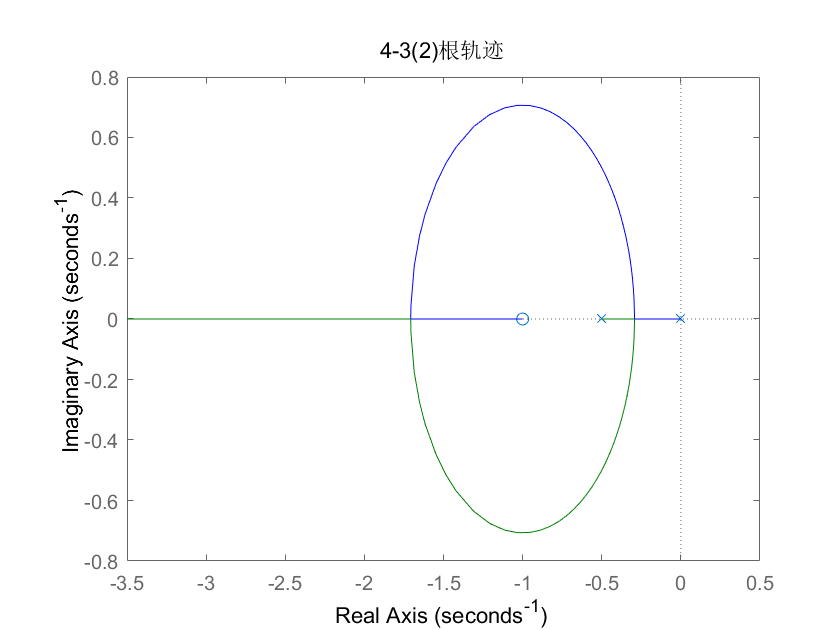

rlocus(G2);
title('4-3(2)根轨迹');

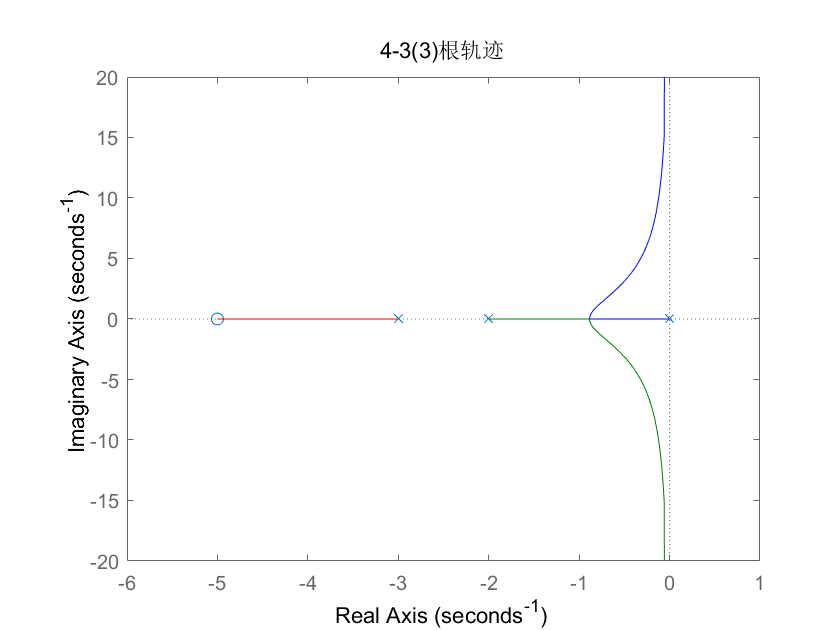

rlocus(G3);
title('4-3(3)根轨迹');

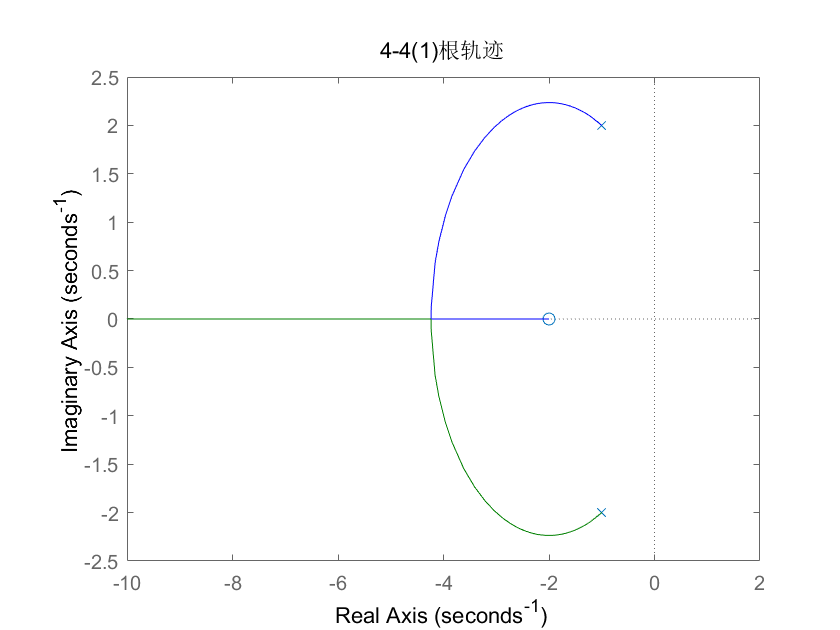

% 4-4
clear
G1 = zpk([-2],[-1-2i -1+2i],1);
G2 = zpk([-20],[0 -10-10i -10+10i],1);
rlocus(G1)
title('4-4(1)根轨迹');

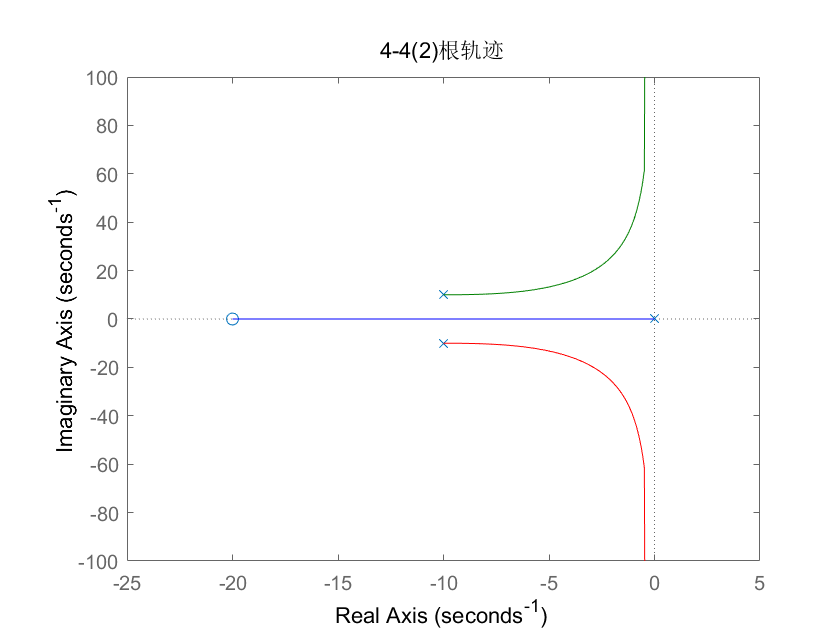

rlocus(G2)
title('4-4(2)根轨迹');

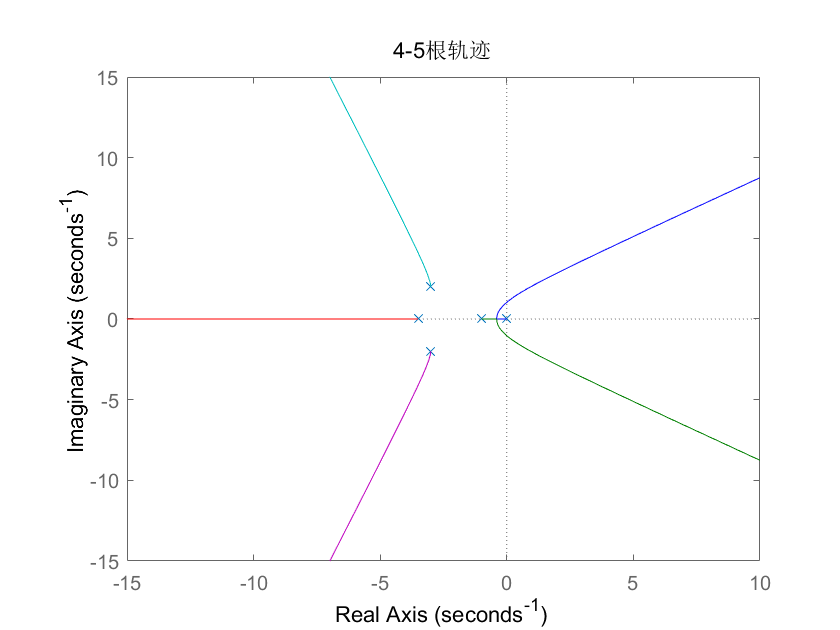

% 4-5
clear
G = zpk([],[0 -1 -3.5 -3-2i -3+2i],1);
rlocus(G);
title('4-5根轨迹');

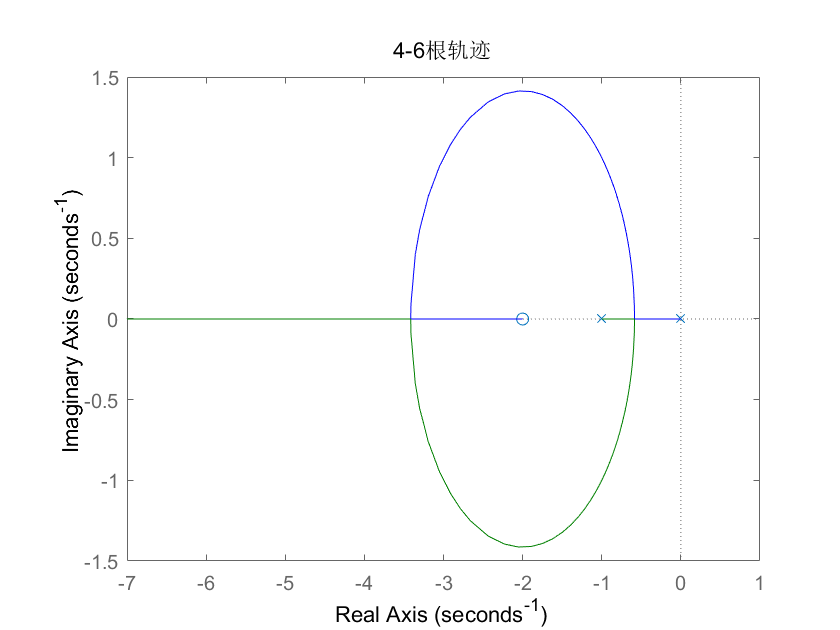

% 4-6
clear
G =zpk([-2],[0,-1],1);
rlocus(G);
title('4-6根轨迹');

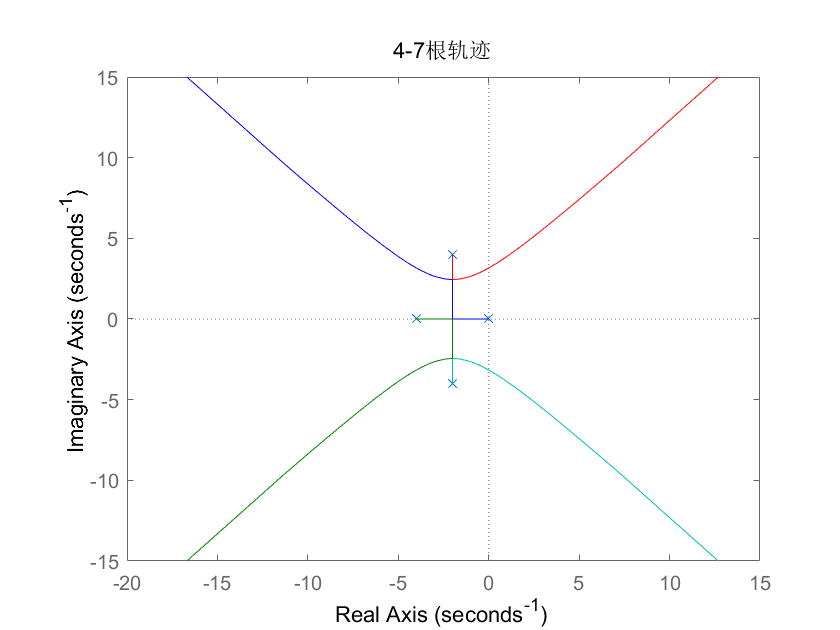

% 4-7
clear
G = zpk([],[0 -4 -2-4i -2+4i],1);
rlocus(G);
title('4-7根轨迹')

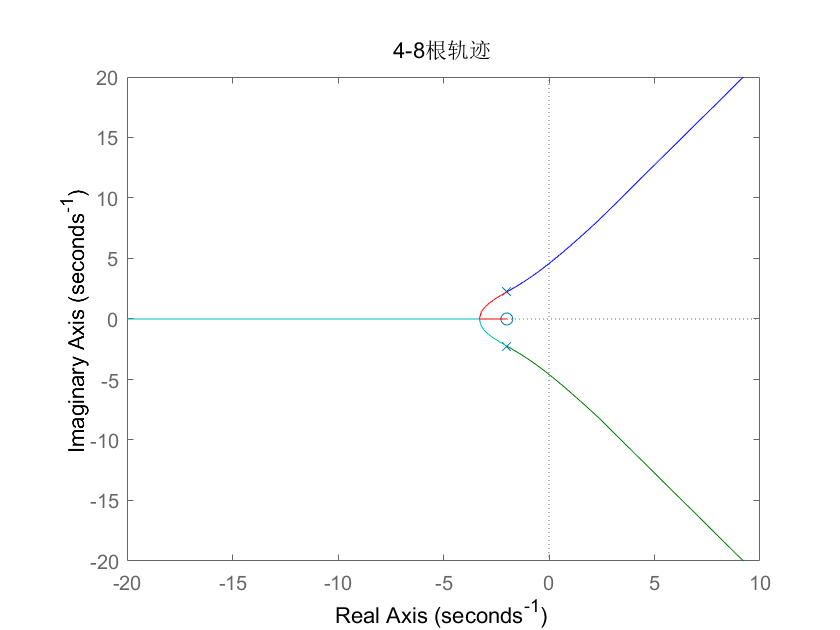

% 4-8
clear
G = zpk([-2],[-2-sqrt(5)*1i -2+sqrt(5)*1i -2-sqrt(5)*1i -2+sqrt(5)*1i],1);
rlocus(G);
title('4-8根轨迹')

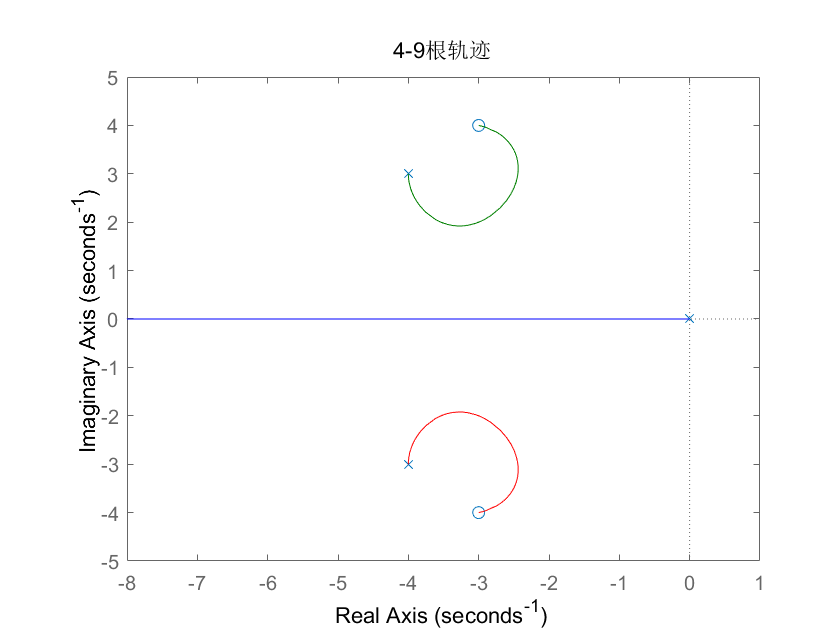

% 4-9
clear
% G = 6.9 * tf([1 6 25],[1 8 25 0]);
% rlocus(G);
% title('4-9根轨迹')
K = 6.9;
rlocus([1 6 25],[1 8 25 0]);
title('4-9根轨迹')

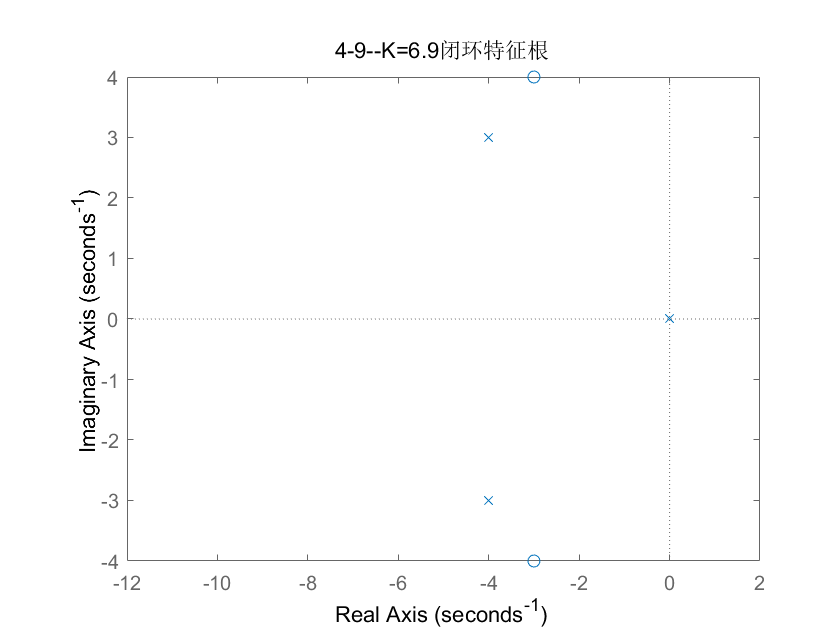

rlocus([1 6 25],[1 8 25 0],K);
title('4-9--K=6.9闭环特征根')

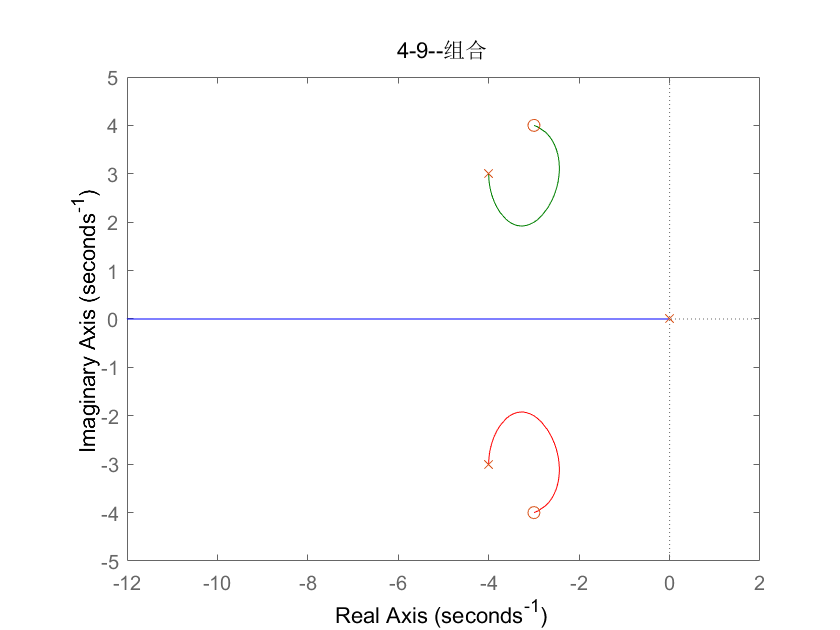


rlocus([1 6 25],[1 8 25 0]);
hold on;
rlocus([1 6 25],[1 8 25 0],K);
title('4-9--组合')
hold off

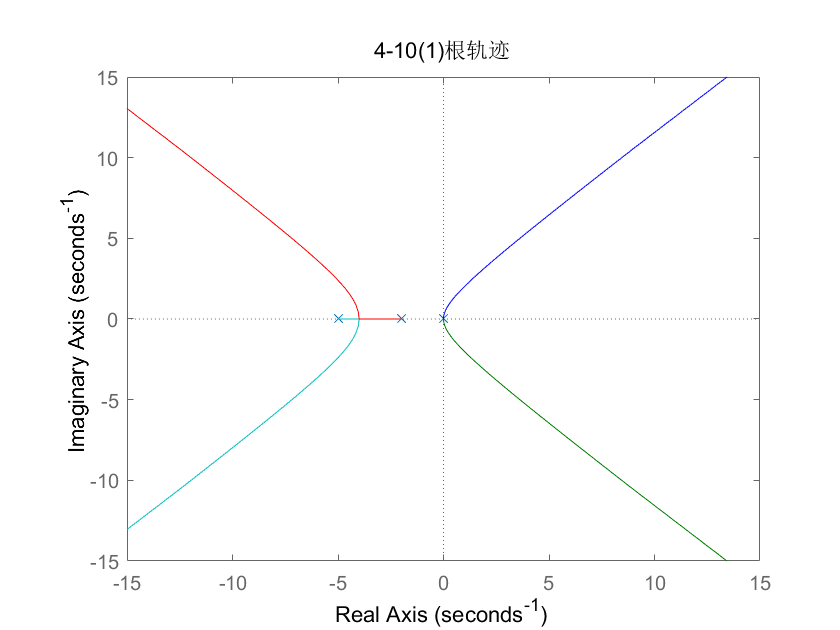

% 4-10
clear
G1 = zpk([],[0 0 -2 -5],1);
G2 = zpk([-0.5],[0 0 -2 -5],1);
rlocus(G1);
title('4-10(1)根轨迹')

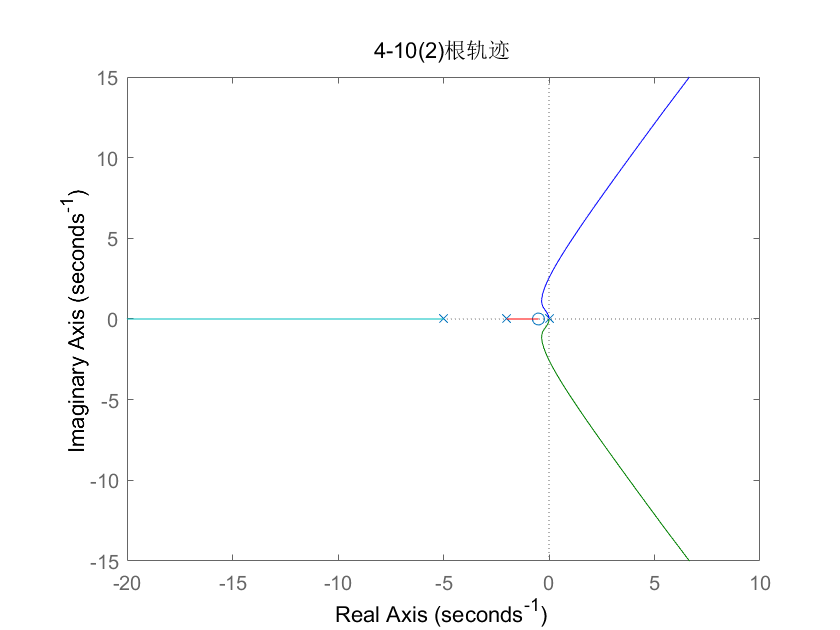

rlocus(G2);
title('4-10(2)根轨迹')

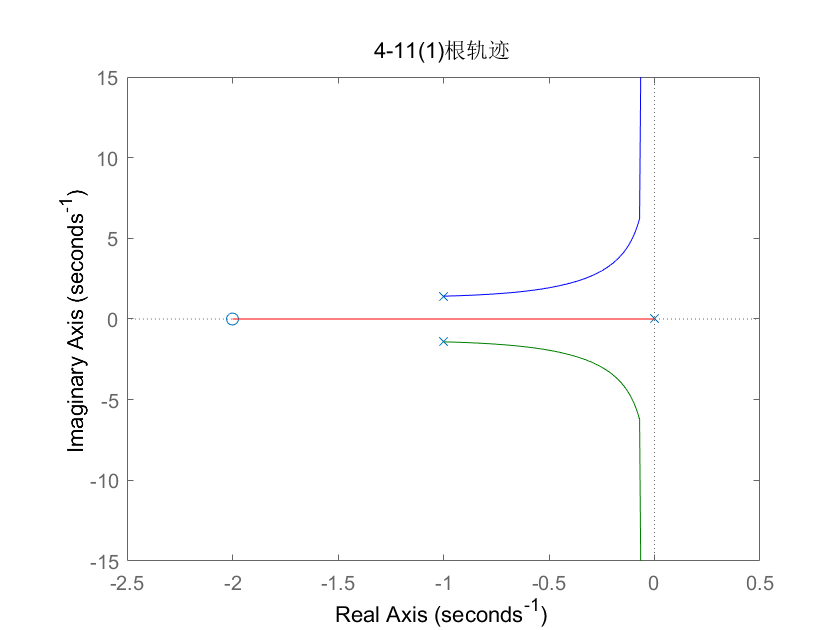

% 4-11
clear
G1 = zpk([-2],[0 -1-sqrt(2)*1i -1+sqrt(2)*1i],1);
G2 = zpk([-10],[0 -1 -2],1);
rlocus(G1);
title('4-11(1)根轨迹');

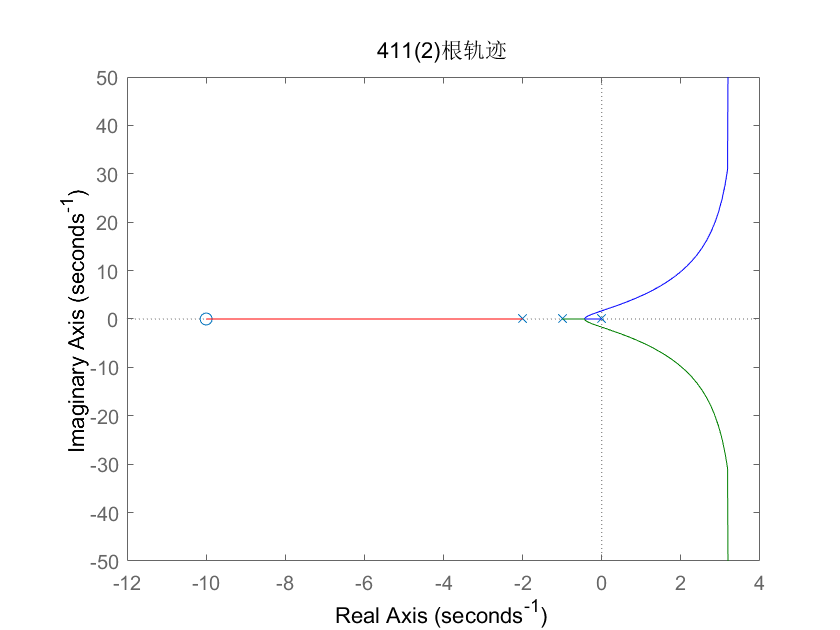

rlocus(G2);
title('411(2)根轨迹');

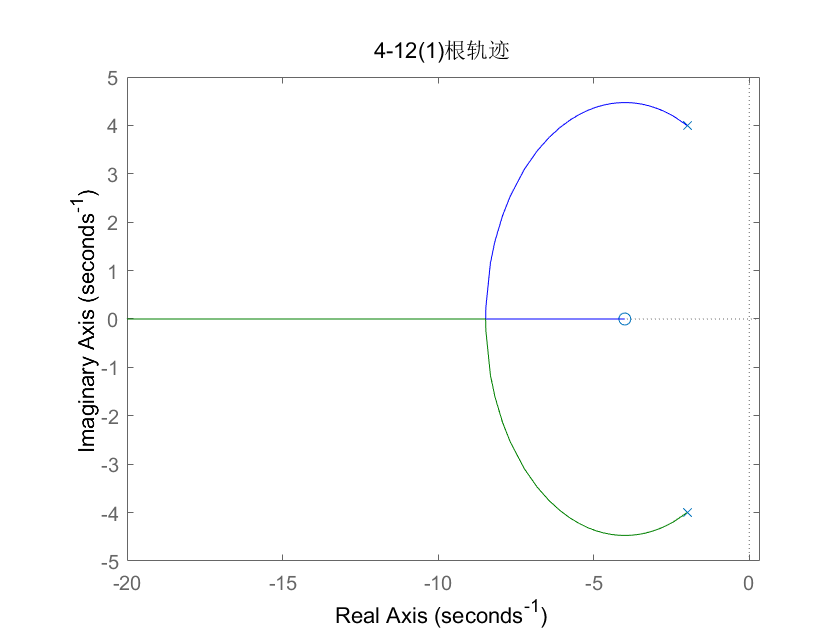

% 4-12
clear
G1 = zpk([-4],[-2-4i -2+4i],1);
G2 = zpk([],[0 -40],1);
rlocus(G1);
title('4-12(1)根轨迹');

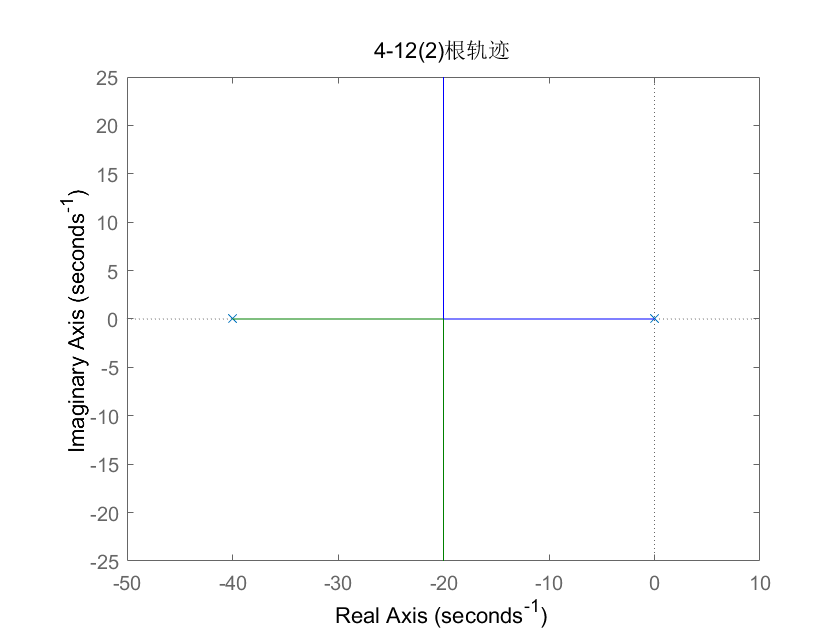

rlocus(G2);
title('4-12(2)根轨迹');

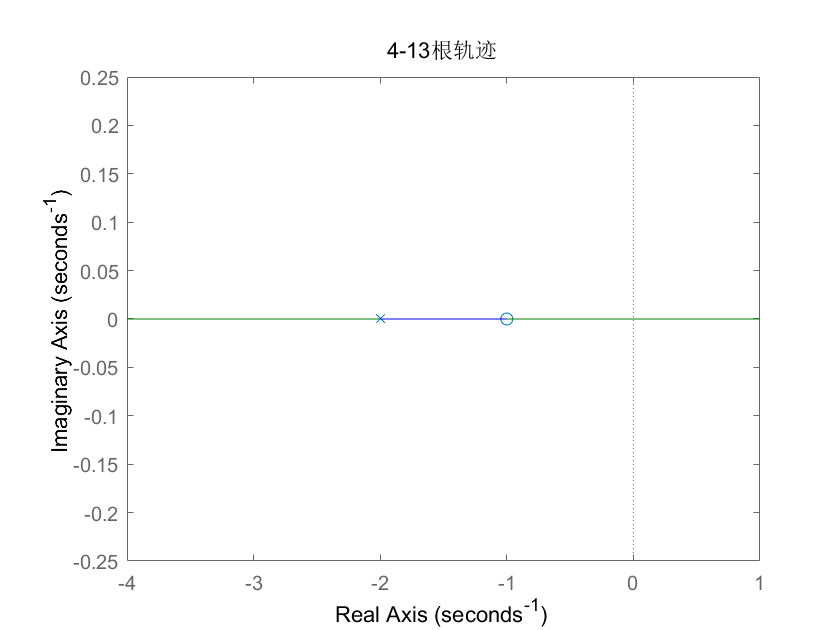

% 4-13  //正反馈
clear
G = zpk([-1 -1],[-2 -2],-1);
rlocus(G);
% grid on;
title('4-13根轨迹');

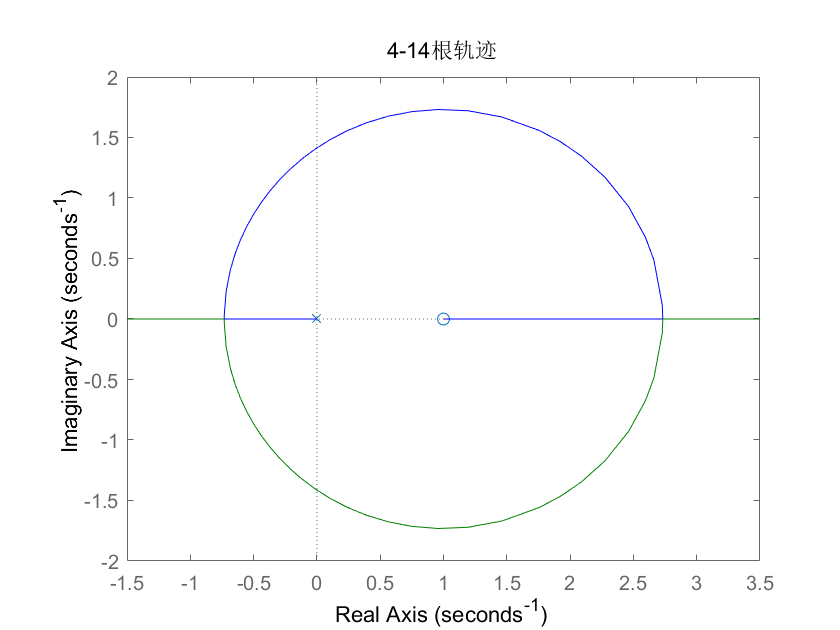

% 4-14  //正反馈
clear
G = zpk([1],[0 -2],-1);
rlocus(G);
axis([-1.5 3.5 -2 2]);
title('4-14根轨迹');

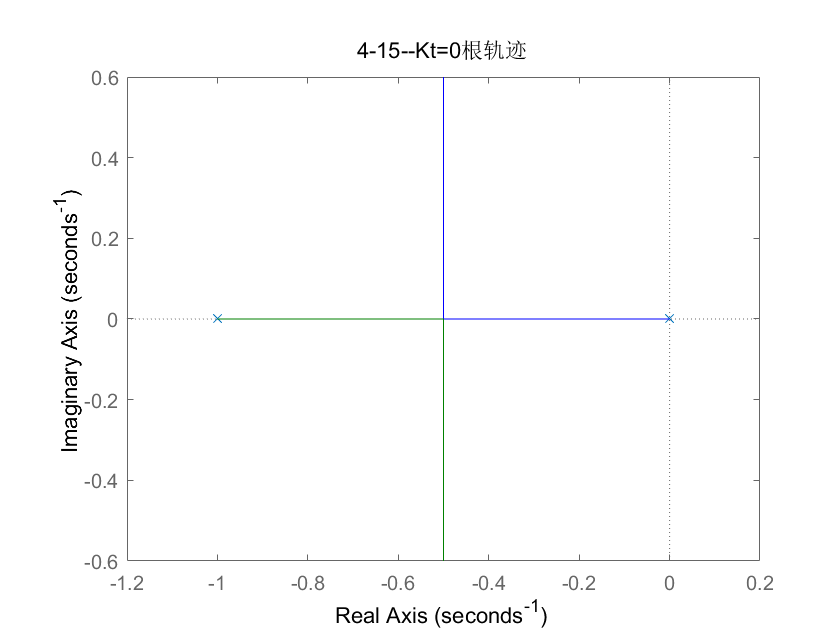

% 4-15
clear
G1 = zpk([],[0 -1],1);
G2 = zpk([-2],[0 -1],1);
G3 = zpk([-0.5],[0 -1],1);
rlocus(G1);
title('4-15--Kt=0根轨迹');

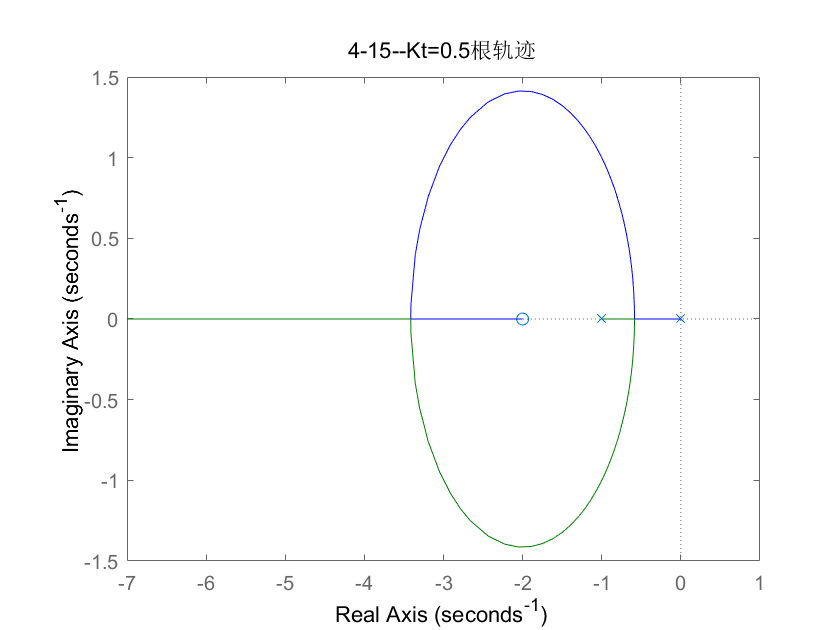

rlocus(G2);
title('4-15--Kt=0.5根轨迹');

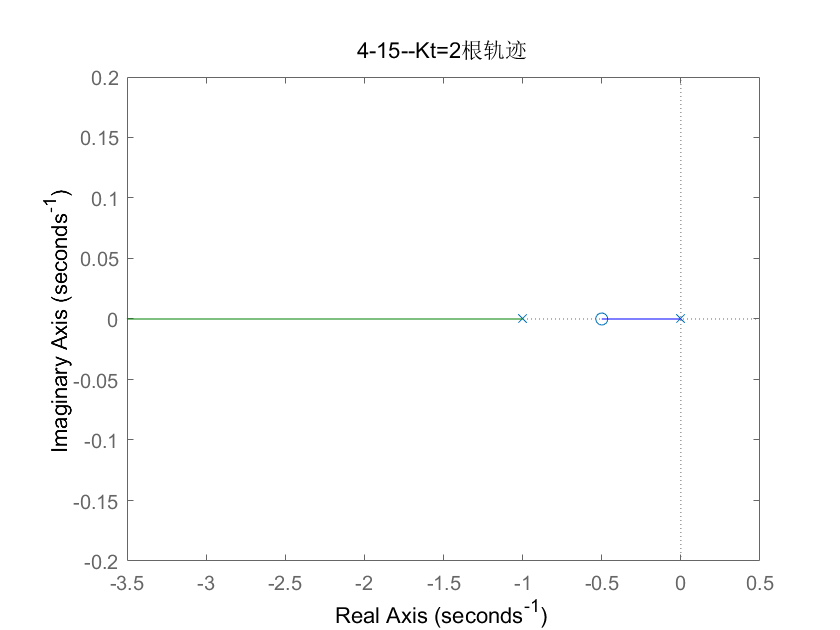

rlocus(G3);
title('4-15--Kt=2根轨迹');

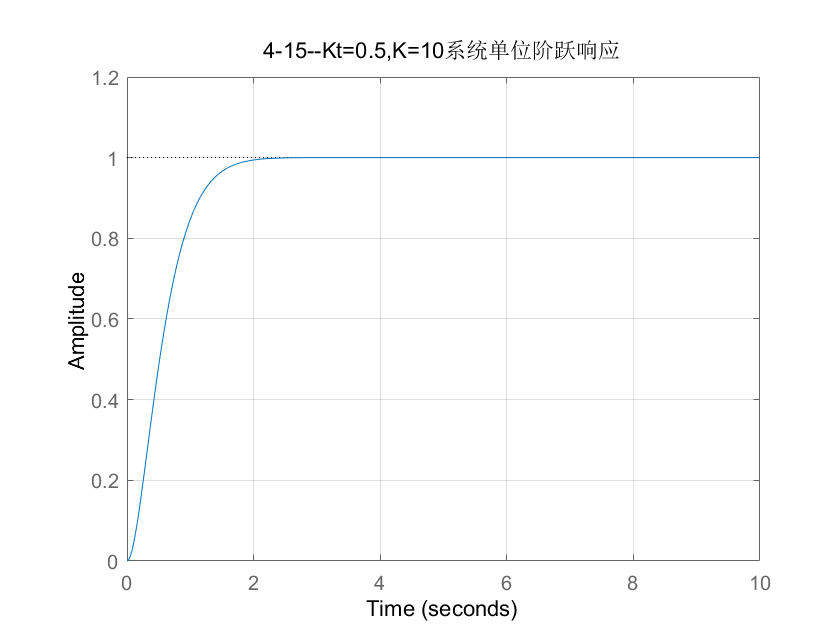


sys = tf([10],[1 6 10]);
t = 0:0.01:10;
step(sys,t),grid on;
title('4-15--Kt=0.5,K=10系统单位阶跃响应');

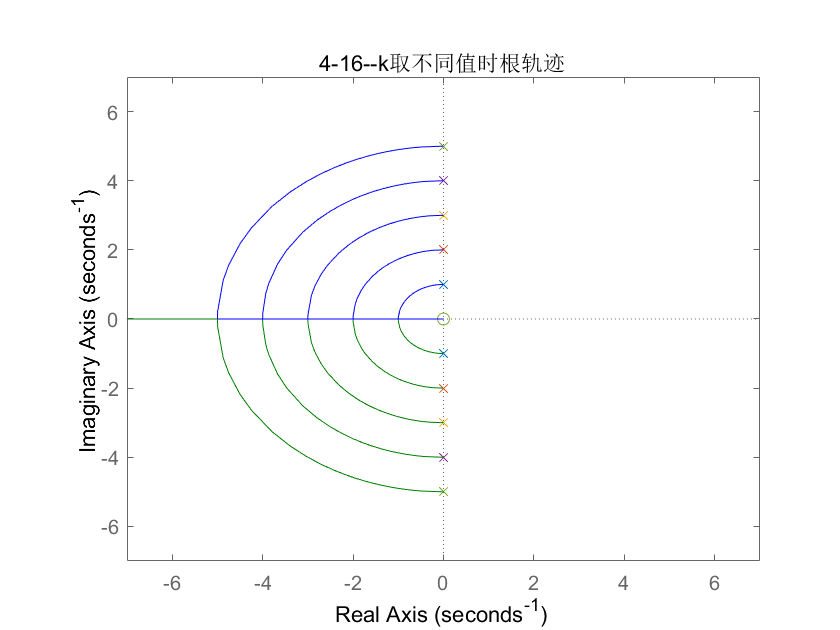

% 4-16
clear
for k = [1 4 9 16 25]
    G = zpk([0],[sqrt(k)*1i -sqrt(k)*1i],1);
    rlocus(G);
    axis([-7,7,-7,7]);
    hold on;
end
title('4-16--k取不同值时根轨迹');
hold off;

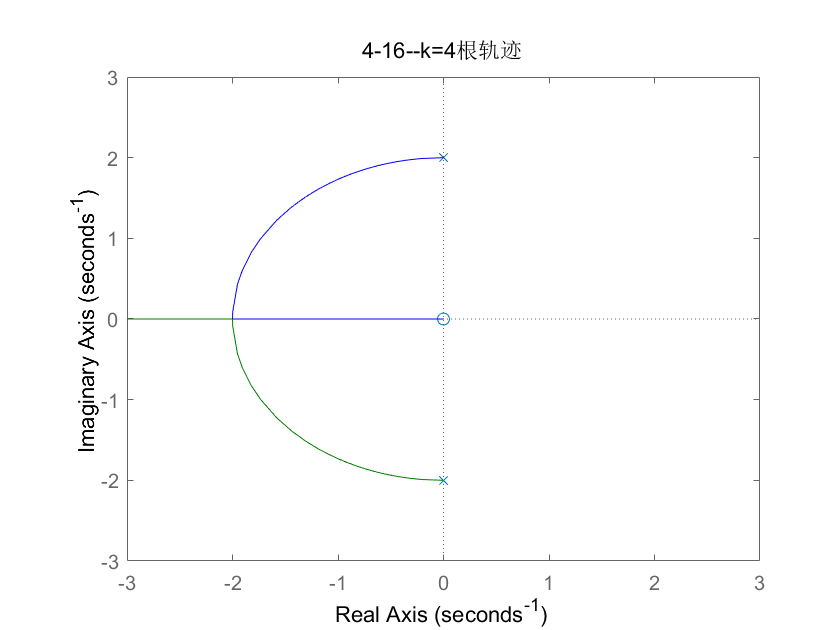

G = zpk([0],[2i -2i],1);
rlocus(G);
title('4-16--k=4根轨迹')
axis([-3,3,-3,3]);

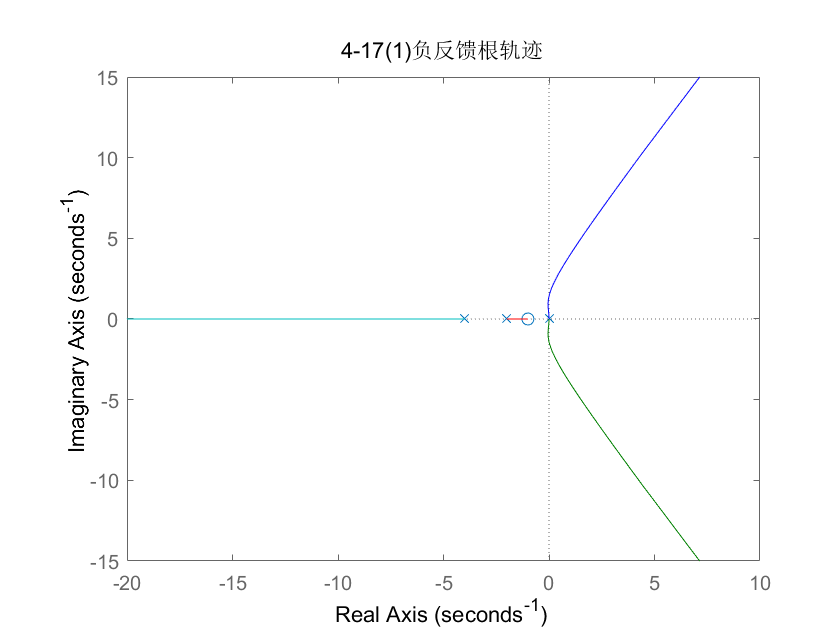

% 4-17
clear
G1 = zpk([-1],[0 0 -2 -4],1);
G2 = zpk([-1],[0 0 -2 -4],-1);
rlocus(G1);
title('4-17(1)负反馈根轨迹');

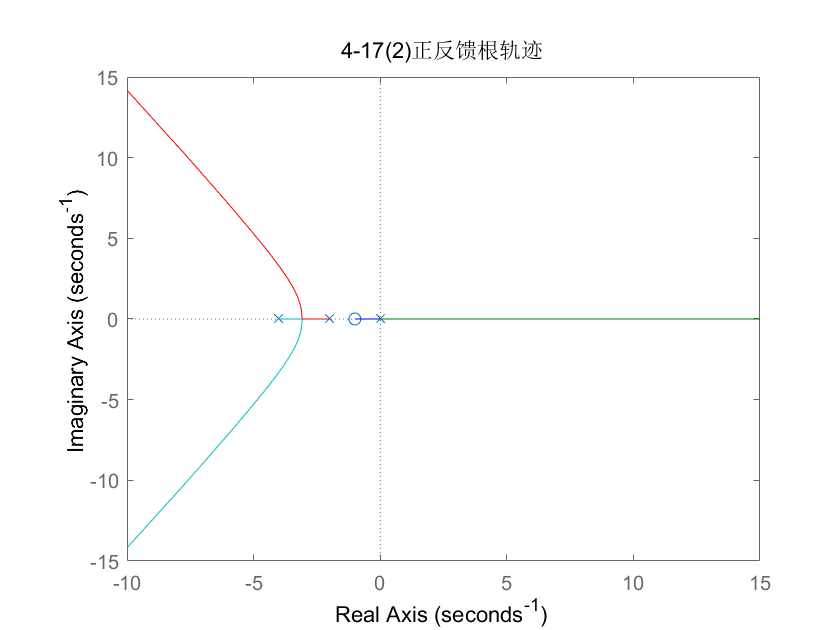

rlocus(G2);
title('4-17(2)正反馈根轨迹');

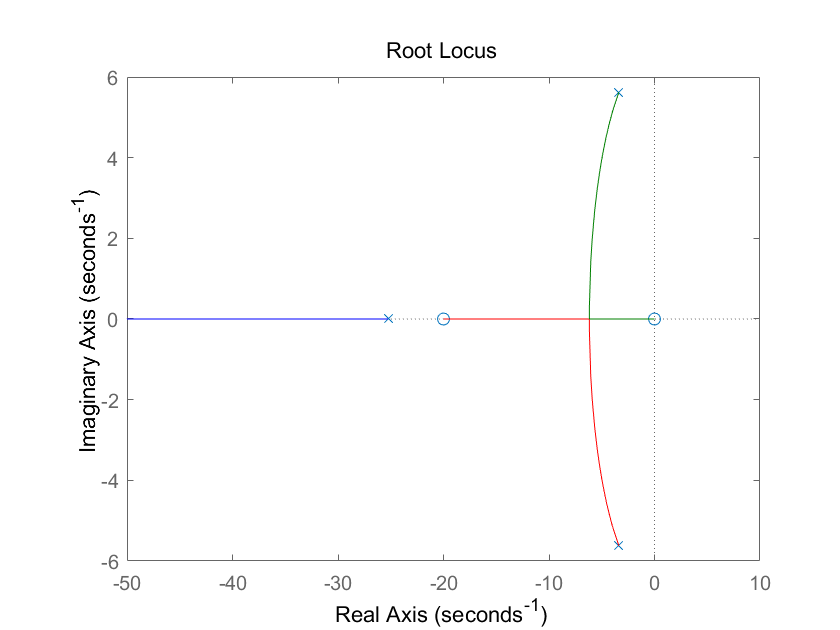

% 4-18
clear
G1 = zpk([0 -20],[-25.25 -3.375-5.625i -3.375+5.625i],1);
G2 = zpk([0 0 -20],[-25.25 -3.375-5.625i -3.375+5.625i],1);
G3 = zpk([0 0],[-25.25 -3.375-5.625i -3.375+5.625i],1);
z = 0.707;
rlocus(G1);

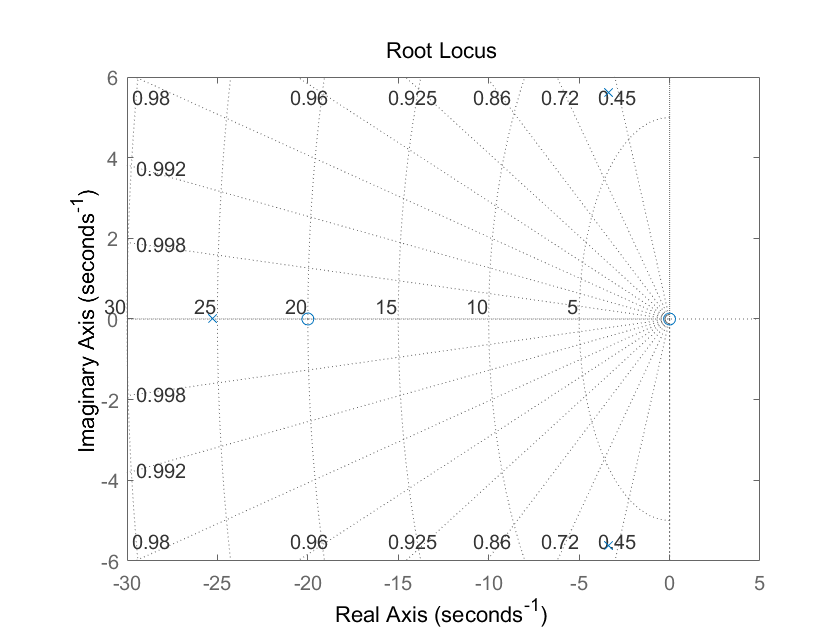

sgrid(z,'new');
K = 3.02;
Kt = K/10;
hold on;
rlocus(G1,K);
hold off;

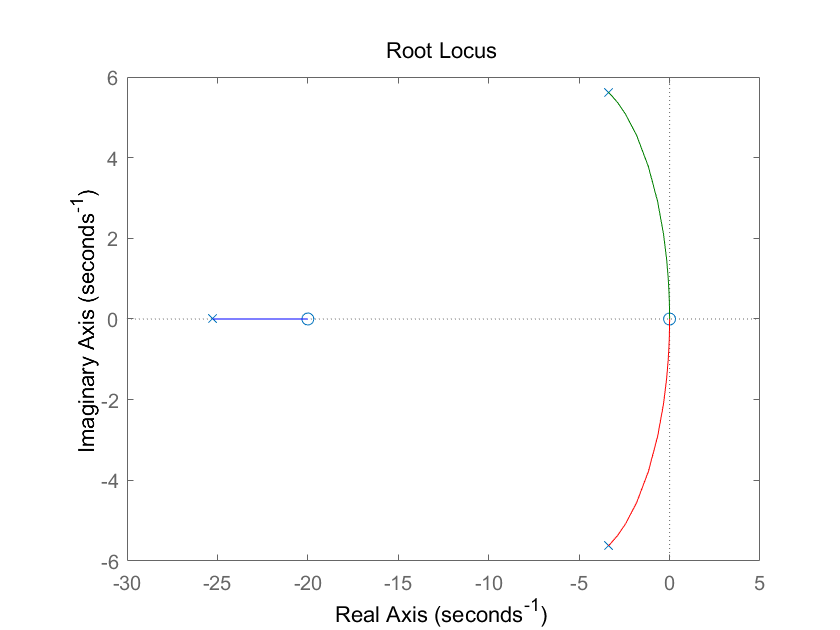


rlocus(G2);

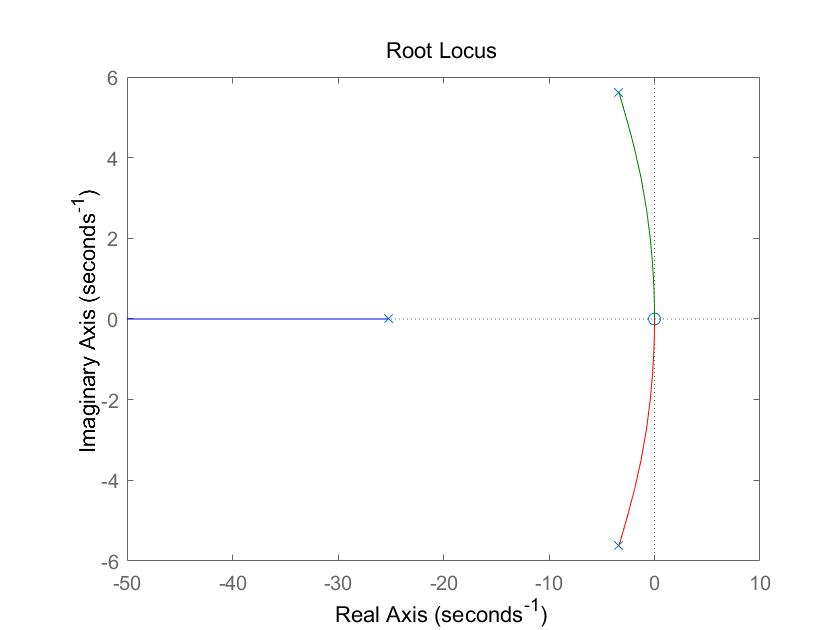

rlocus(G3);


num1 = [100],den1 = [1 20];

num1 = 100

num2 = [10],den2 = [1 10 0];

num2 = 10

num3 = [Kt 0],den3 = [0 0 1];

num3 =     0.3020         0


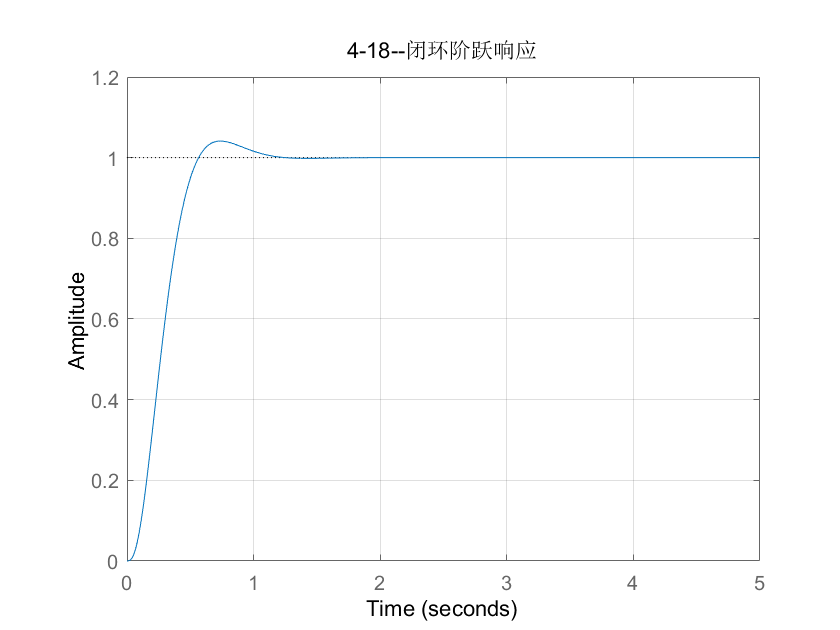

[numf,denf] = feedback(num2,den2,num3,den3);
[numc,denc] = series(num1,den1,numf,denf);
[num,den] = cloop(numc,denc);
sys = tf(num,den);
t = 0:0.001:5;
step(sys,t),title('4-18--闭环阶跃响应'),grid on;

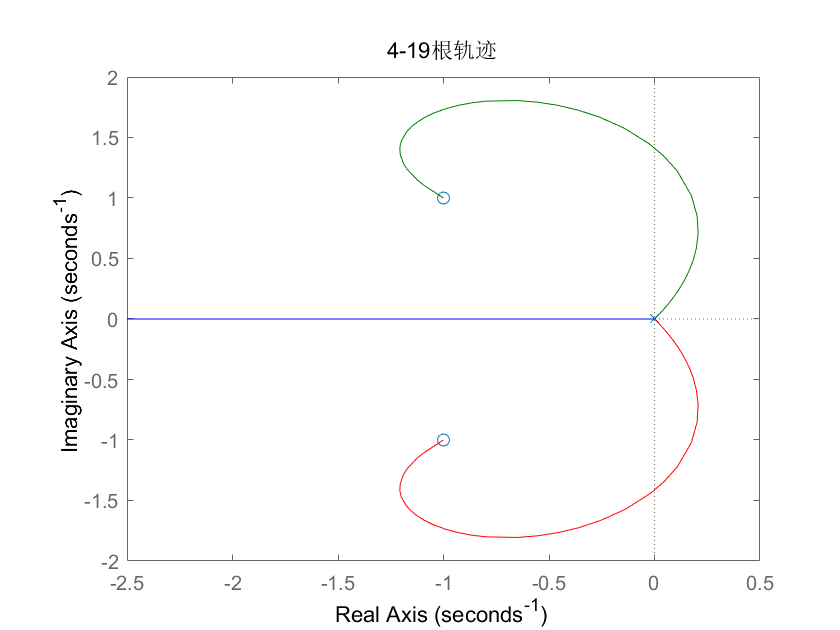

% 4-19
clear
G = zpk([-1-1i -1+1i],[0 0 0],1);
rlocus(G);
title('4-19根轨迹');

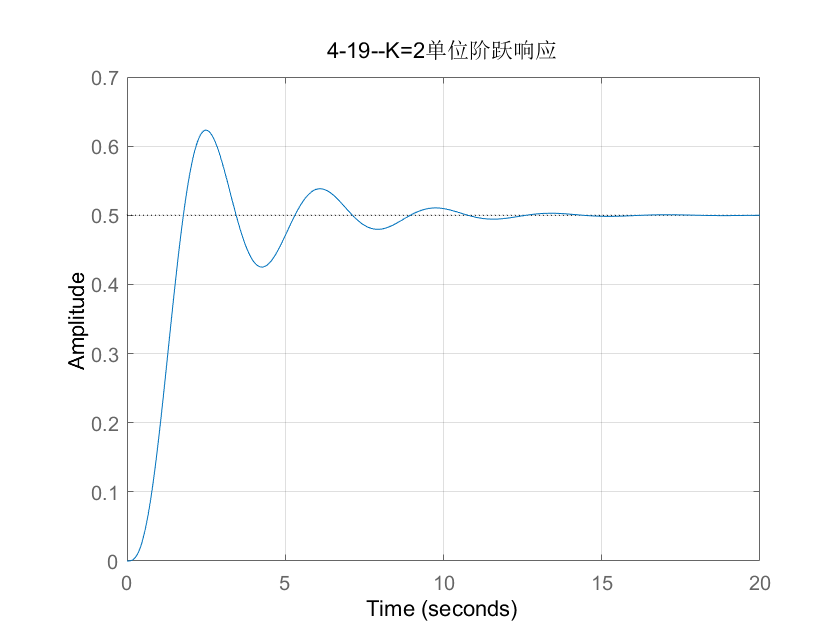

% K = 2时单位阶跃响应
[num1,den1] = feedback([2],[1 0 0 0],[1 2 2],[0 0 1]);
sys1 = tf(num1,den1);
t = 0:0.01:20;
step(sys1,t),grid on;
title('4-19--K=2单位阶跃响应');

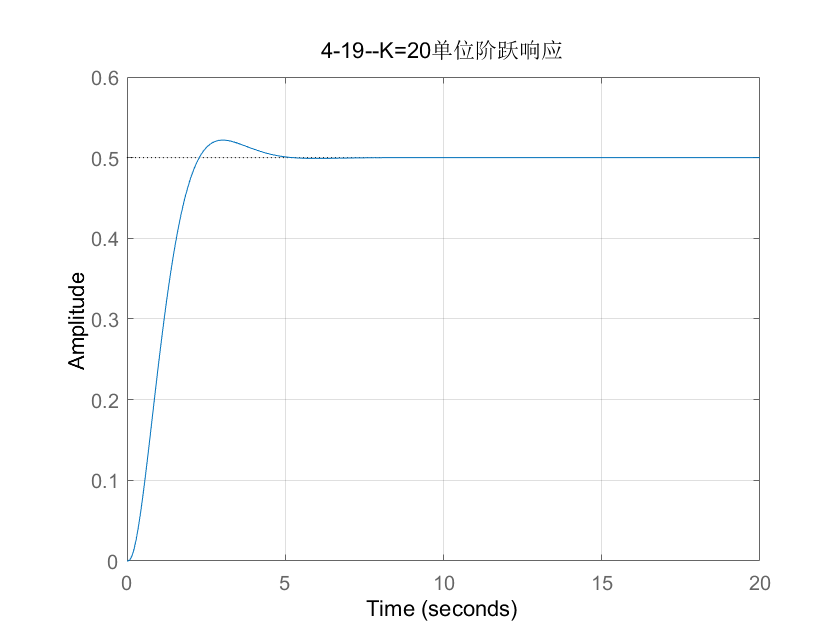

% K = 20时单位阶跃响应
[num1,den1] = feedback([20],[1 0 0 0],[1 2 2],[0 0 1]);
sys2 = tf(num1,den1);
t = 0:0.01:20;
step(sys2,t),grid on;
title('4-19--K=20单位阶跃响应');

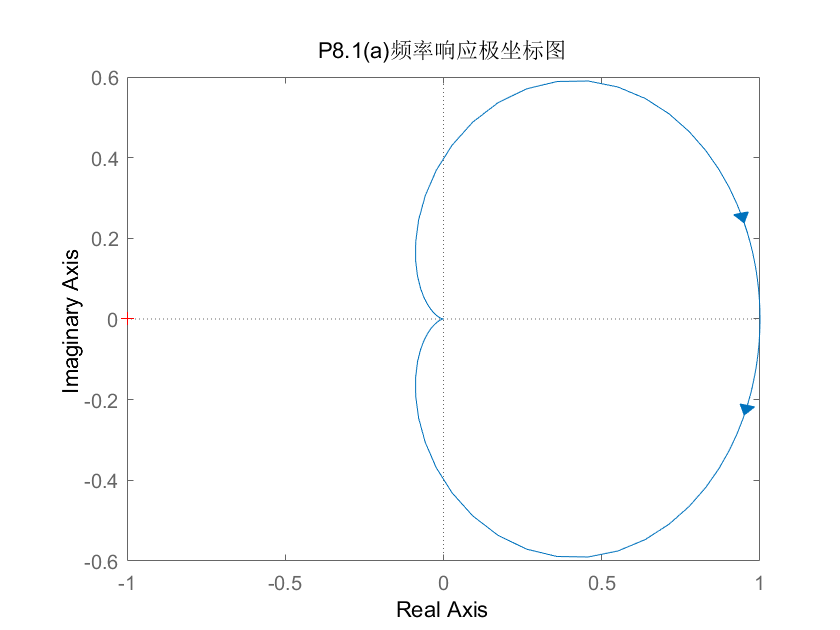

% P8.1
clear
G1 = tf([1],conv([0.5 1],[2 1]));
nyquist(G1);
title('P8.1(a)频率响应极坐标图')


G2 = tf([30 240],conv(conv([1 0],[1 2]),[1 4]))

G2 =
 
     30 s + 240
  -----------------
  s^3 + 6 s^2 + 8 s
 
Continuous-time transfer function.



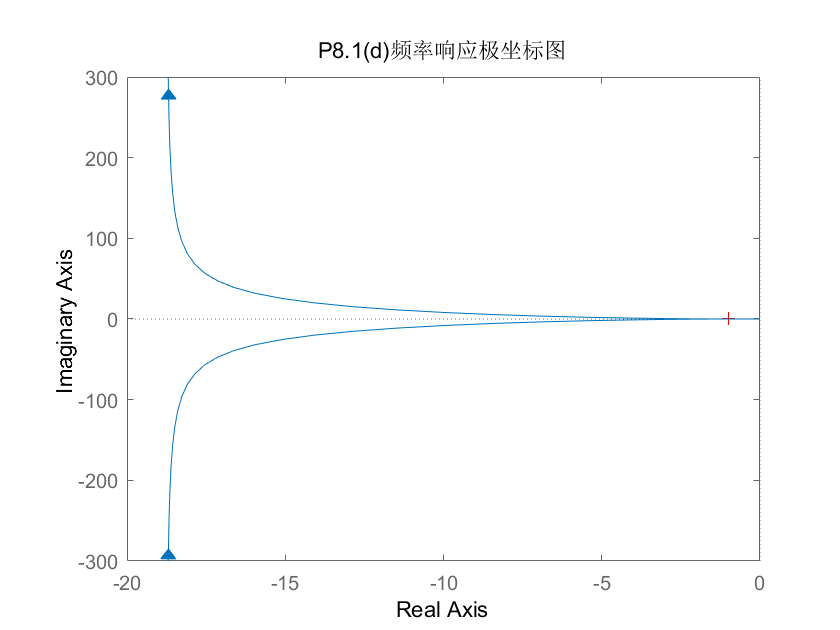

nyquist(G2);
title('P8.1(d)频率响应极坐标图')

% P8.5
clear
K = 10;
f1 = [0.2 1],f2 = [1 1],f3 = [0.1 1],f4 = [1/50 1];

f1 =     0.2000    1.0000


f2 =      1     1


f3 =     0.1000    1.0000


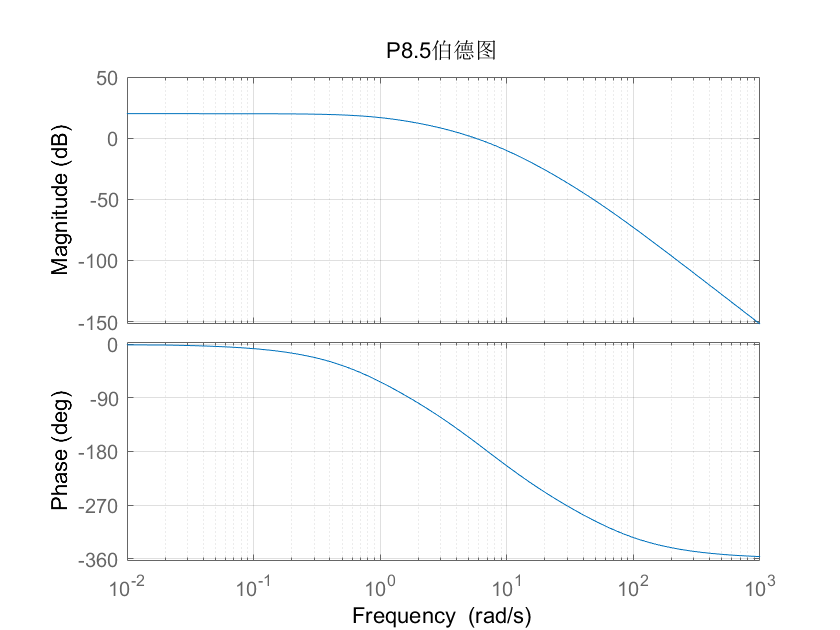

den = conv(conv(f1,f2),conv(f3,f4));
sys = tf([K],den);
bode(sys),grid on;
title('P8.5伯德图')

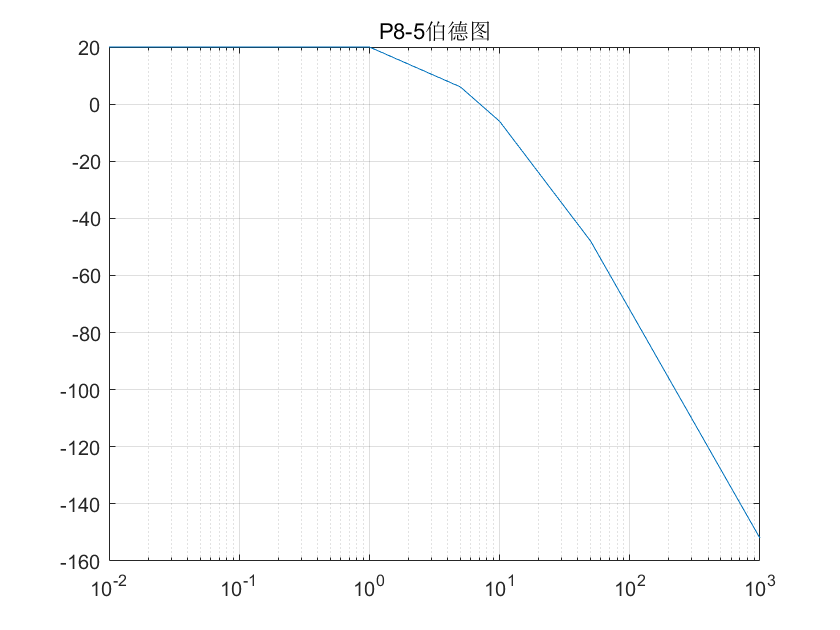



w = 10e-3:0.01:10e2;
[x,y] = bd_asymp(sys,w);
semilogx(x,y),grid on,title('P8-5伯德图');

A = tf([1],[1 2 1])

A =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



B = zpk([],[-1 -1],[1])

B =
 
     1
  -------
  (s+1)^2
 
Continuous-time zero/pole/gain model.



% 附录子程序

% function [wpos,ypos]=bd_asymp(G,w)
% G1=zpk(G); Gtf=tf(G);
% if nargin==1,
%     w=freqint2(Gtf.num{1},Gtf.den{1},100);
% end
% zer=G1.z{1}; pol=G1.p{1}; gain=G1.k;
% wpos=[]; pos1=[];
% for i=1:length(zer);
%     if isreal(zer(i))
%         wpos=[wpos, abs(zer(i))];
%         pos1=[pos1,20];
%     else
%         if imag(zer(i))>0
%             wpos=[wpos, abs(zer(i))];
%             pos1=[pos1,40];
%         end
%     end
% end
% for i=1:length(pol);
%     if isreal(pol(i))
%         wpos=[wpos, abs(pol(i))];
%         pos1=[pos1,-20];
%     else
%         if imag(pol(i))>0
%             wpos=[wpos, abs(pol(i))];
%             pos1=[pos1,-40];
%         end
%     end
% end
% wpos=[wpos w(1) w(length(w))];
% pos1=[pos1,0,0];
% [wpos,ii]=sort(wpos); pos1=pos1(ii);
% ii=find(abs(wpos)<eps); kslp=0;
% w_start=1000*eps;
% if length(ii)>0,
%     kslp=sum(pos1(ii));
%     ii=(ii(length(ii))+1):length(wpos);
%     wpos=wpos(ii); pos1=pos1(ii);
% end
% while 1
%     [ypos1,pp]=bode(G,w_start);
%     if isinf(ypos1), w_start=w_start*10;
%     else
%         break; 
%     end
% end
% wpos=[w_start wpos];
% ypos(1)=20*log10(ypos1);
% pos1=[kslp pos1];
% for i=2:length(wpos)
%     kslp=sum(pos1(1:i-1));
%     ypos(i)=ypos(i-1)+...
%     kslp*log10(wpos(i)/wpos(i-1));
% end
% ii=find(wpos>=w(1)&wpos<=w(length(w)));
% wpos=wpos(ii); ypos=ypos(ii);
% end
% 
% 